# Radiation Treatment Planning Demonstration

This software project implements a quadratic programming formulation of radiation treatment planning, roughly according to Section 2.3 of Hamid Ghaffari's [2012 Ph.D. thesis](https://tspace.library.utoronto.ca/handle/1807/34010) for the University of Toronto. The following MATLAB LiveScript steps through this planning process for a toy example consisting of a cubic tumor within a spherical brain (see `customRegionsDemo.m` to select custom regions from a brain MRI slice).

## Setting Up Initial Parameters

As input, the treatment planning process needs a description of the structures of interest, the number of desired isocenters, collimator sizes, and dosage parameters. This example is run in 2D to produce slightly cleaner visualizations, but, by swapping `[N N]` to `[N N N]` in the second line, the entire demo can also be run in 3D.

N = 50; R = N/2;
gridSize = [N N]; % = [N N N];
coordinates = voxelgrid.CoordinateData(gridSize);

brainCenter = floor(gridSize / 2) + 1;
brainRadius = R * 0.95;
tumorCorner1 = brainCenter - gridSize/4;
tumorCorner2 = brainCenter + gridSize/4;

numIsocenters = 20;
collimatorSizes = R * [0.05 0.1 0.25];
alpha = 0.8; % closeness acceptance factor
f = 0.15; % relaxation factor

% Structure 1 - Healthy Tissue, Structure 2 - Tumor
healthyTissueMinDose = 0;
healthyTissueMaxDose = 1;
healthyTissueUnderdosingWeight = 0;
healthyTissueOverdosingWeight = 1;
tumorMinDose = 2;
tumorMaxDose = 5;
tumorUnderdosingWeight = 1;
tumorOverdosingWeight = 1;

## Initializing Structure Assignments

Next, we generate a matrix the size of our voxel grid which assigns each voxel to a structure label (1, 2, ..., # structures). The label 0 is reserved for unassigned voxels which do not play a role in optimization.

healthyTissue = zeros(gridSize);
healthyTissue = voxelgrid.setSphere(healthyTissue, coordinates, ...
                                    brainCenter, brainRadius, 1);
tumor = zeros(gridSize);
tumor = voxelgrid.setAABB(tumor, coordinates, ...
                          tumorCorner1, tumorCorner2, 1);
healthyTissue = healthyTissue - tumor;
structureAssignments = 1*healthyTissue + 2*tumor;

Structure assignments visualized:

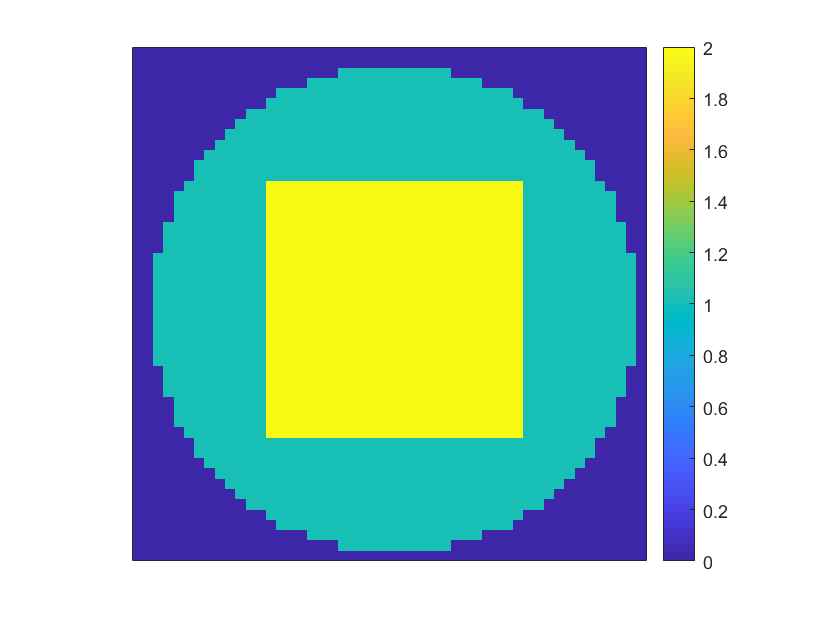

voxelgrid.displayGrid(structureAssignments);

## Generating Isocenters

According to our model, radiation treatment consists of a series of shots administered for specified durations. Each shot is determined by a location, called an isocenter, and a collimator size. We select a relatively small set of isocenters over which to optimize according to the grassfire method described by Ghobadi et al. in a [2012 paper](https://www.ncbi.nlm.nih.gov/pubmed/22755698). It should be possible to avoid restricting the isocenter set so much, but this is a straightforward way of making the optimization problem tractible. However, the isocenter selection algorithm makes some crude assumptions which should be analyzed further.

isocenters = planning.genIsocenters(tumor, coordinates, numIsocenters, ...
                                    collimatorSizes, alpha, f);

Isocenter set visualized (works best in 2D):

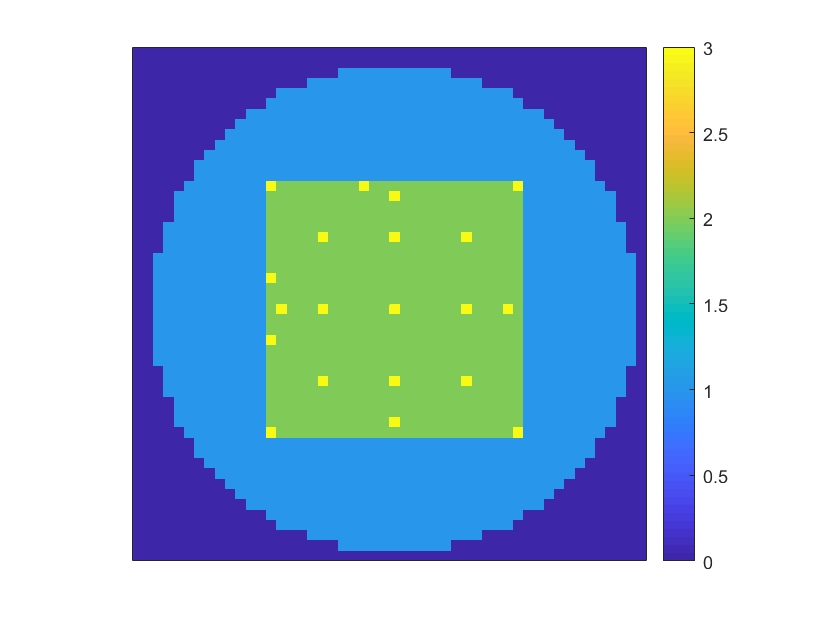

temp = structureAssignments;
numStructures = max(temp(:));
isocenterLabel = numStructures + 1;
for isocenter = 1:size(isocenters,1)
    loc = num2cell(isocenters(isocenter,:));
    temp(loc{:}) = isocenterLabel;
end
voxelgrid.displayGrid(temp);

## Calculating Dose Rates

Dose rates from the treatment device are assumed to be Gaussian, with standard deviation dependent on collimator size. This could clearly be improved by using some sort of simulation.

doseRates = cell(length(isocenters), length(collimatorSizes));
for i = 1:length(isocenters)
    for j = 1:length(collimatorSizes)
        c = isocenters(i,:);
        s = collimatorSizes(j);
        doseRates{i,j} = planning.getDoseRate(coordinates, c, s);
    end
end

Example dose rate visualized:

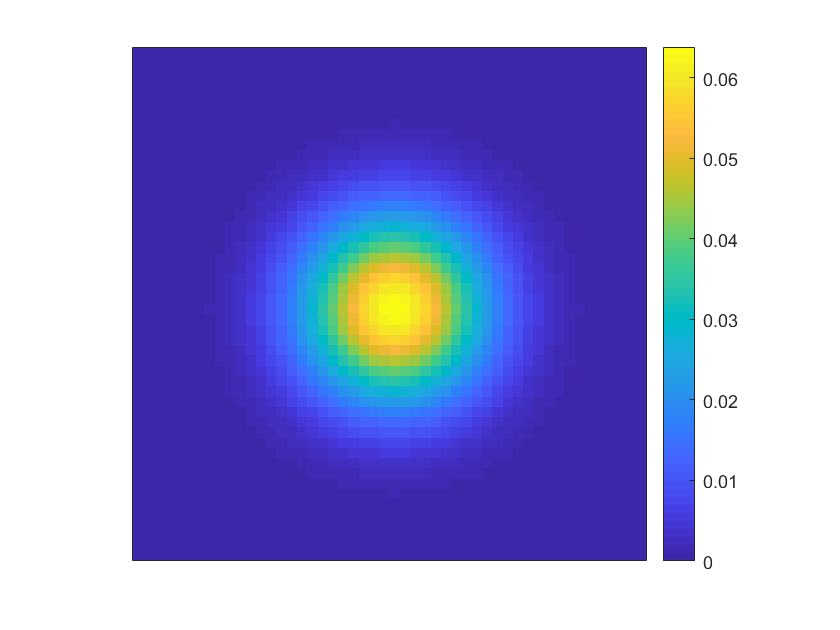

voxelgrid.displayGrid(doseRates{1,3});

## Generating the Treatment Plan

Now we have everything that we need to begin the optimization process. We use a quadratic programming formulation of the optimization problem which minimizes the sum of the following penalty over all voxels (equation 2.2 of Ghaffari's [thesis](https://tspace.library.utoronto.ca/handle/1807/34010)):

$\frac{1}{v_s}\left[\underline{w}_s\left(z_{js} - \underline{T}_s\right)_+^2 + \overline{w}_s\left(z_{js} - \overline{T}_s\right)_+^2\right]$,

where $j$ is the voxel in question, $s$ is its structure, $(\cdot)_+=\max\{\cdot,0 \}$, $\underline{w}_s, \overline{w}_s$ are over- and under-dosing weights, and $\underline{T}_s, \overline{T}_s$ are the threshold doses at which penalties are incurred.

minDosePerStructure = [healthyTissueMinDose tumorMinDose];
maxDosePerStructure = [healthyTissueMaxDose tumorMaxDose];
underdosingWeights = [healthyTissueUnderdosingWeight, ...
                      tumorUnderdosingWeight];
overdosingWeights = [healthyTissueOverdosingWeight, ...
                     tumorOverdosingWeight]; 

plan = planning.genTreatmentPlan(structureAssignments, ...
                                 minDosePerStructure, ...
                                 maxDosePerStructure, ...
                                 underdosingWeights, overdosingWeights, ...
                                 doseRates);

Starting quadprog.

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

Treatment plan visualized:

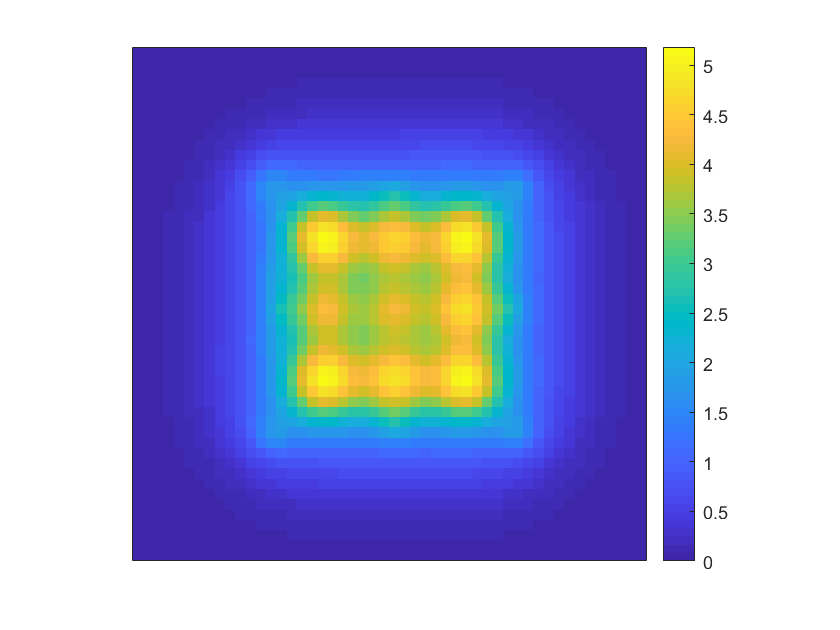

voxelgrid.displayGrid(plan.totalDoses);

Volume for which no penalties were applied (excluding unassigned voxels):

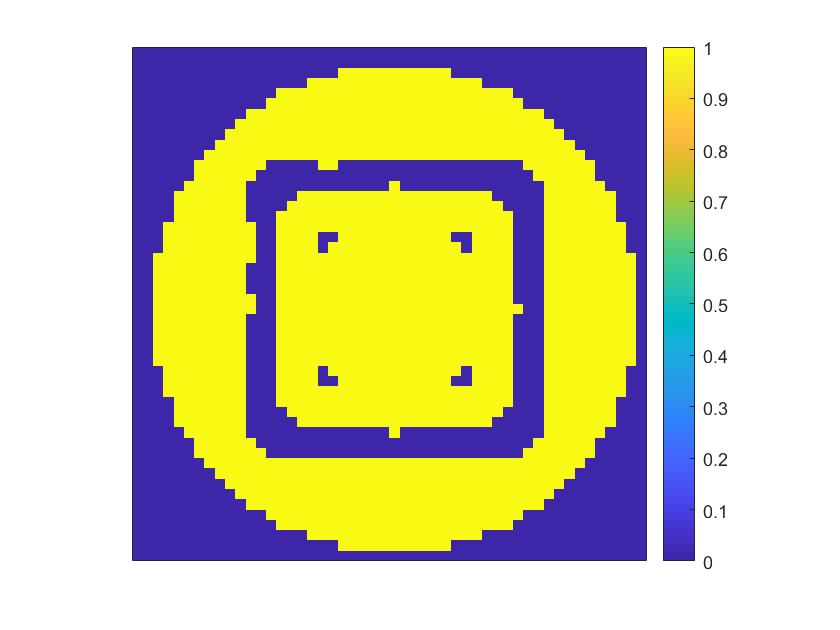

satisfied = and(plan.totalDoses < plan.maxDoses, ...
                plan.totalDoses > plan.minDoses);
voxelgrid.displayGrid(satisfied);